% read an input 

train1_1 = imread('train_images/Set1/1.jpg');
train1_2 = imread('train_images/Set1/2.jpg');
train1_3 = imread('train_images/Set1/3.jpg');


## To Grayscale

train1_1 = rgb2gray(train1_1);
train1_2 = rgb2gray(train1_2);
train1_3 = rgb2gray(train1_3);

## Corner Detection

cm1_1 = cornermetric(train1_1);
cm1_2 = cornermetric(train1_2);
cm1_3 = cornermetric(train1_3);


## ANMS Test

Nbest = 200;

lm1_1 = imregionalmax(cm1_1);


[x,y] = find(lm1_1);

N_Strong = size(x,1);

r = inf(1,N_Strong);
ED = 0;

for i = 1:N_Strong
    for j = 1:N_Strong
        if cm1_1(x(j),y(j)) > cm1_1(x(i),y(i))
           ED =  (x(j)-x(i))^2 + (y(j)-y(i))^2;
           if ED < r(i)
              r(i) = ED;
           end 
        end
    end
end    

[sort_r,index] = sort(r,'descend');


## Test function


a = [2 4 6 8 10]
b = find(a > 3)

## ANMS Step

Nbest = 200;
c_best_1_1 = ANMS(cm1_1,Nbest);
c_best_1_2 = ANMS(cm1_2,Nbest);
c_best_1_3 = ANMS(cm1_3,Nbest);


## display


imshow(train1_1);
hold on;
scatter(c_best_1_1(2,:),c_best_1_1(1,:),'r.')
hold off;

imshow(train1_2);
hold on;
scatter(c_best_1_2(2,:),c_best_1_2(1,:),'r.')
hold off;

imshow(train1_3);
hold on;
scatter(c_best_1_3(2,:),c_best_1_3(1,:),'r.')
hold off;



## Feature Descriptor

H = fspecial('gaussian',40,0.5);

f_vector_1_1 = f_descriptor(c_best_1_1,train1_1,H)
f_vector_1_2 = f_descriptor(c_best_1_2,train1_2,H)
f_vector_1_3 = f_descriptor(c_best_1_3,train1_3,H)


## Feature Matching

% ssd
b_ssd = 0;
sb_ssd = 0;
mp_1_1_2 = zeros(2,size(c_best_1_2,2));
for j = 1:size(f_vector_1_1,2)
    ssd = 0;
    for k = 1:64 
        ssd = ssd + ((f_vector_1_1(k,1) - f_vector_1_2(k,j))^2); 
    end
    if ssd > b_ssd 
        sb_ssd = b_ssd;
        b_ssd = ssd;
        mp_1_1_2(:,1) = c_best_1_2(:,j);
            
    elseif ssd > sb_ssd 
        sb_ssd = ssd;
    end      
end
c_best_1_1(:,1)
b_ssd 
sb_ssd 
mp_1_1_2(:,1)
ratio = b_ssd/sb_ssd 



## try from p5

threshold = 10^5;
maxi = 30;
matchedpts1;
matchedpts2;
X = zeros(4,1);
Y = zeros(4,1);
x = zeros(4,1);
y = zeros(4,1);
percentage = 0;
% random no.
j=0;
while j <= 100 && percentage < 90
    for i = 1:4
        r = randi(size(matchedpts1,1));
        X(i,1) = matchedpts1(r,1);
        Y(i,1) = matchedpts1(r,2);
        x(i,1) = matchedpts2(r,1);
        y(i,1) = matchedpts2(r,2);
    end
    
    H = est_homography(X,Y,x,y);
    [X1, Y1] = apply_homography(H,matchedpts1(:,1), matchedpts1(:,2));    
    SSD(:,1) = matchedpts2(:,1) - X1 ;
    SSD(:,2) = matchedpts2(:,2) - Y1;
    SSD_n = SSD(:,1) + SSD(:,2);
    SSD_n = SSD_n.^2;
    if size(SSD_n(SSD_n < threshold),1)/size(SSD_n,1)*100 > percentage 
        percentage = size(SSD_n(SSD_n < threshold),1)/size(SSD_n,1)*100;
        inliers = find(SSD_n < threshold);
    end
    j = j + 1;
end
percentage

percentage = 87.9310

inliers;

inliers_1 = matchedpts1(inliers,:)

inliers_1 =    450    33
   419   282
   222    18
   417   427
   152   289
   199   151
   297   395
   299   232
   289   576
   447   594


inliers_2 = matchedpts2(inliers,:)

inliers_2 =    191   414
   188   221
   261    61
   432   237
    72   388
    71   223
   450   131
   448     1
   403   361
   231   564



H = est_homography(inliers_1(:,1),inliers_1(:,2),inliers_2(:,1),inliers_2(:,2))

H =     0.0014    0.0012   -0.6974
    0.0015    0.0012   -0.7166
    0.0000    0.0000   -0.0018


[X1, Y1] = apply_homography(H,inliers_1(:,1), inliers_1(:,2));  
match_1 = [X1 Y1]

match_1 = 	1.0e+04 *

    0.0425   -0.0403
    0.0390    0.0426
    0.0387    0.0389
    0.0390    0.0416
    0.0380    0.0372
    0.0385    0.0383
    0.0393    0.0427
    0.0453    0.0980
    0.0391    0.0414
    0.0390    0.0411


[X2, Y2] = apply_homography(H,inliers_2(:,1), inliers_2(:,2));  
match_2 = [X2 Y2] 

match_2 = 	1.0e+03 *

    0.4067    0.4670
    0.3830    0.3757
    0.3869    0.3827
    0.3891    0.4303
    0.3770    0.3754
    0.3846    0.3912
    0.3875    0.4572
    0.3951    0.2780
    0.3899    0.4203
    0.3929    0.4173


## Show

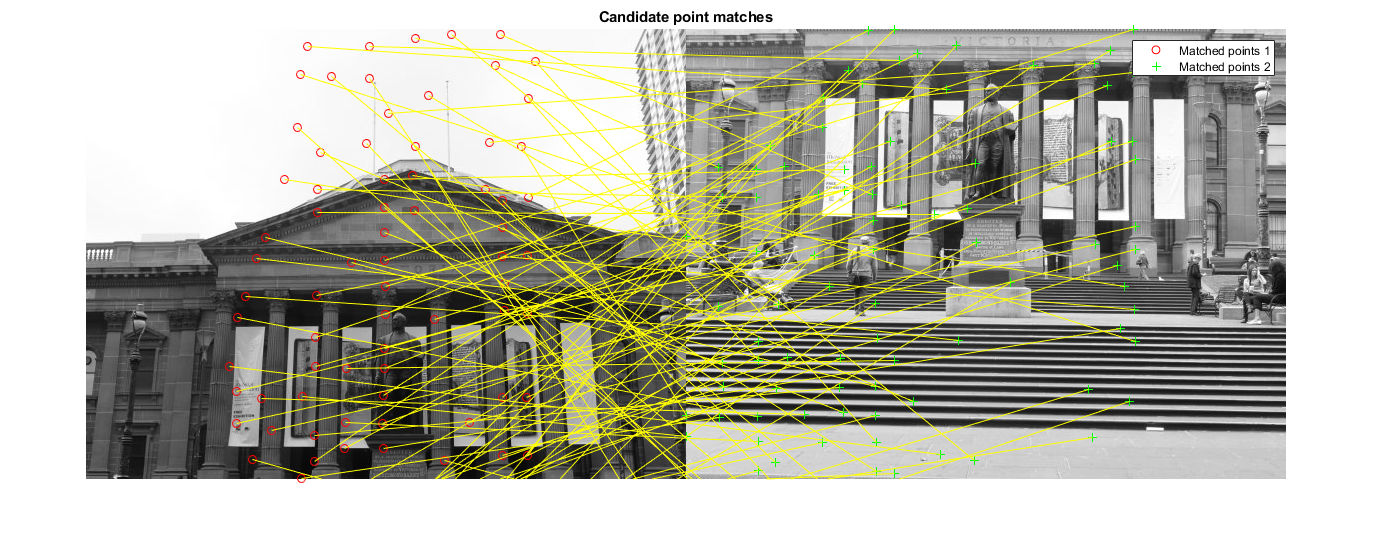


figure; ax = axes;
showMatchedFeatures(train1_1,train1_2,inliers_1,inliers_2,'montage','Parent',ax);
title(ax, 'Candidate point matches');
legend(ax, 'Matched points 1','Matched points 2');

## Function

function c_best = ANMS(cm,Nbest)

lm = imregionalmax(cm);


[x,y] = find(lm);

N_Strong = size(x,1);

r = inf(1,N_Strong);
ED = 0;

for i = 1:N_Strong
    for j = 1:N_Strong
        if cm(x(j),y(j)) > cm(x(i),y(i))
           ED =  (x(j)-x(i))^2 + (y(j)-y(i))^2;
           if ED < r(i)
              r(i) = ED;
           end 
        end
    end
end    

[sort_r,index] = sort(r,'descend');
c_best = zeros(2,Nbest);

for i = 1:Nbest
    c_best(1,i) = x(index(i)); 
    c_best(2,i) = y(index(i));
end
end

function f_vector = f_descriptor(cbest,I,H)
f_vector = zeros(64,size(cbest,2));
for i = 1:size(cbest,2)
    minx = max(1,cbest(1,i)-20);
    maxx = min(size(I,1),cbest(1,i)+19);
    miny = max(1,cbest(2,i)-20);
    maxy = min(size(I,2),cbest(2,i)+19);
    im_40 = I(minx:maxx,miny:maxy);
    b_40 = imfilter(im_40,H,'replicate');
    b_8 = imresize(b_40,[8 8]);
    f_vector(:,i) = b_8(:);  
    f_vector(:,i) = f_vector(:,i) - ones(64,1)*mean(f_vector(:,i));
    f_vector(:,i) = f_vector(:,i)/std(f_vector(:,i));
end
end





